# Preprocessing for Cluster Based Permutation Testing - written for data collected with predictive T-Maze task using 32 electrode EEG montage

Designed for data pre-processed in BrainVision Analyzer version 2.3. Preprocessing includes interpolation of channels *(where necessary), ocular correction, artifact rejection, segmentation, and averaging of ERPs across trials. This portion takes in a folder with a csv file with ERP data for each participant reconstructs data from all individual suject files into one table formats one table

REQUIREMENTS SubID "key" that decodes which subject ID is associated with either condition (e.g. ruminator vs nonruminator or excitatory vs inhibitory TMS protocol); a folder that contains files directly exported from BrainVision analyzer - there should be one file for each participant that contains data for ERP averaged over trials at every millisecond for each channel recorded.

## Set folder path and initialize variables

group1 = 'Inhibitory'; % update for group titles based on CondKey
group2 = 'Excitatory'; % update for group titles based on CondKey
groups = [string(group1), string(group2)]

groups = 1×2 string array
    "Inhibitory"    "Excitatory"


folderPath = "C:\Users\mallo\OneDrive\Desktop\ClusterBasedPermutationTesting\Data\InputData\datFiles_StimorInhib";
files = dir(fullfile(folderPath, '*.csv'));
SubID_condKey = readtable("C:\Users\mallo\OneDrive\Desktop\ClusterBasedPermutationTesting\Data\InputData\SubList_StimType.xlsx");
nPermutations = 20; %number of permutations; can be adjusted; 1000 generally accepted minimum
timePoints = 800; %total number of timepoints being investigated; can be adjusted based on length of ERP extracted from BrainVision
alpha = 0.05; % significance for final 'true' clusters
null_alpha = 0.01; % alpha for significance during null permutations

## Create a list of subIDs

SubList = table();
for file = 1:length(files);
    fileName = files(file).name;
    SubID_Sub = erase(fileName, '.csv');
    Dat = string(SubID_Sub);
    tabDat = table(Dat);
    SubList = vertcat(SubList, tabDat);
end

SubList.Properties.VariableNames = "SubID";

## Reconstruct single table with data from all timepoints for each participant

allData = table();
for sub = 1:height(SubList); % loops through subID list made in previous step
    subData = readtable(fullfile(folderPath, SubList.SubID(sub)));
    numRows = height(subData);
    subIDColumn = repmat(SubList.SubID(sub), numRows, 1); %repeats subject ID for number of rows associated with that participant's data
    subData.SubID = subIDColumn; % adds subID column to the new table
    subGroupColumn = repelem(SubID_condKey.StimType(sub), numRows, 1); % uses subID "key" to assign participants to a group 
    subData.Group = subGroupColumn; % adds group membership identifier
    for i = 1:width(subData)
        colData = subData{:,i};
        if any(strcmp(colData, 'Cz'));
            subData.Properties.VariableNames{i} = 'Channel';
            break
        end
    end
    allData = vertcat(allData, subData);
end

## Update Variable Order and Names

colsToMove = {'SubID', 'Group'};  % columns you want at the beginning
allVars = allData.Properties.VariableNames;
newOrder = [colsToMove, setdiff(allVars, colsToMove, 'stable')];
allData = allData(:, newOrder);

% Define fixed columns
fixedCols = {'SubID', 'Group', 'Channel'};

% Identify timepoint columns (everything else)
timeCols = setdiff(allData.Properties.VariableNames, fixedCols, 'stable');

% Build full list of new variable names
varNames = [fixedCols, strcat("Time", string(1:length(timeCols)))];

% Assign new variable names
allData.Properties.VariableNames = varNames;

## Filter for channels of interest

allData = allData(ismember(allData.Channel, ["FCz", "Fz", "Cz"]), :); %editable! Can add any channels by adding the string name for the channel

channels = string(unique(allData.Channel));
nChannels = length(channels);

# Raw Data Visualization for CBPT script

creates a grand average ERP waveform and superimposes the interquartile range over the grand average ERP wave Charts individual waveforms from each participant at each electrode; helps to identify potential outliers Creates histograms for amplitudes at assumed key points in the data (i.e. hypothesized P3 and N2 peak as well as a baseline timepoint) also helpful for identifying outliers

## Grand Average ERP Waveforms with Interquartile Range

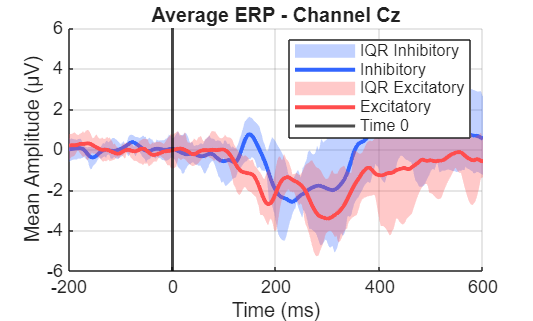

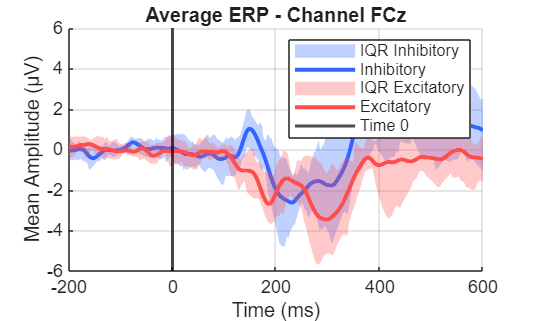

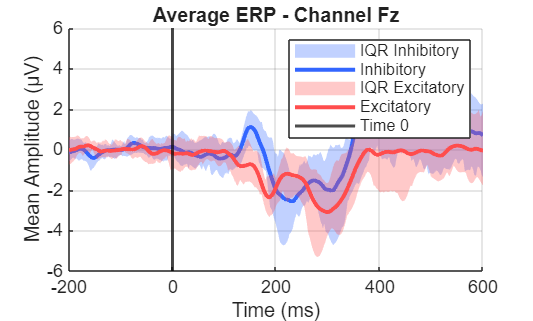

time = linspace(-200, 600, timePoints);

groupColors = [
    0.2 0.4 1.0;   % Blue-ish for Group 1
    1.0 0.3 0.3    % Reddish for Group 2
];
for chan = 1:length(channels)
    % Get channel name
    chanName = channels(chan);
    
    % Extract data for that channel
    chanDat = allData(strcmp(allData.Channel, chanName), :);
    
    % Open figure ONCE per channel
    figure('WindowStyle','docked');
    hold on;

    for group = 1:length(groups)
        % Extract data for this group within the channel
        groupCode = group;  % 1 or 2
        groupDat = chanDat(chanDat.Group == groupCode, :);
        
        % Find amplitude columns
        ampCols = contains(groupDat.Properties.VariableNames, 'Time');
        
        % Compute mean across subjects
        meanAmplitudes = mean(groupDat{:, ampCols}, 1);  % 1 x 800
        q25 = prctile(groupDat{:, ampCols}, 25, 1);
        q75 = prctile(groupDat{:, ampCols}, 75, 1);
        fill([time, fliplr(time)], [q25, fliplr(q75)], ...
            groupColors(group, :), ...
            'FaceAlpha', 0.3, ...
            'EdgeColor', 'none', ...
            'DisplayName', char("IQR " + groups(group)));
        
        % Plot
        plot(time, meanAmplitudes, ...
            'DisplayName', groups(group), ...
            'Color', groupColors(group, :), ...
            'LineWidth', 2);
    end

    xlabel('Time (ms)');
    ylabel('Mean Amplitude (µV)');
    title(sprintf('Average ERP - Channel %s', chanName));
    ylim([-6 6]);
    xlim([min(time) max(time)]);
    xline(0, 'k', 'LineWidth', 1.5, 'DisplayName', 'Time 0');
    legend('Location', 'best');
    grid on;
end

## Histogram

Choosing a few key timepoints; helps to identify potential outliers x-axis will display mean ERP amplitudes at specified timepoint y-axis shows how many participants displayed that amplitude

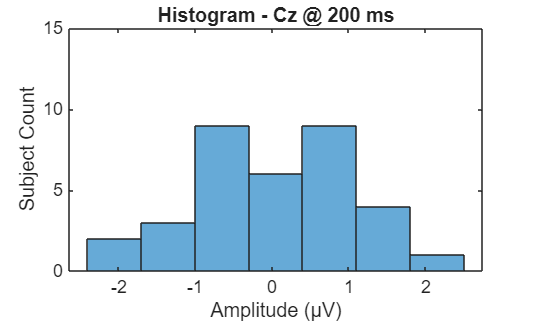

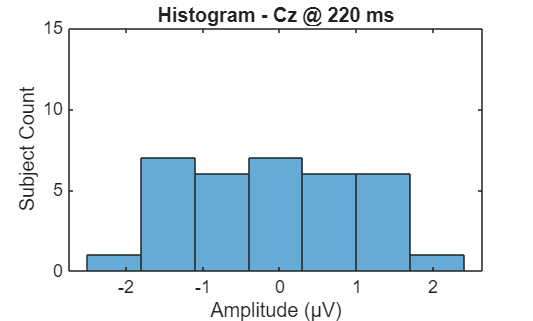

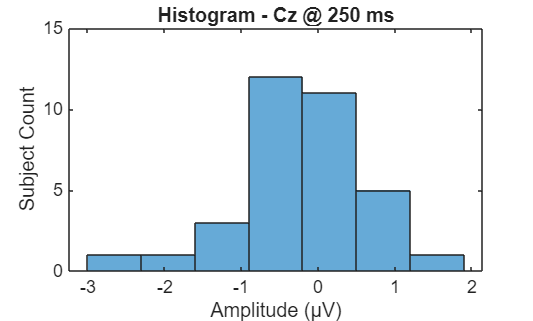

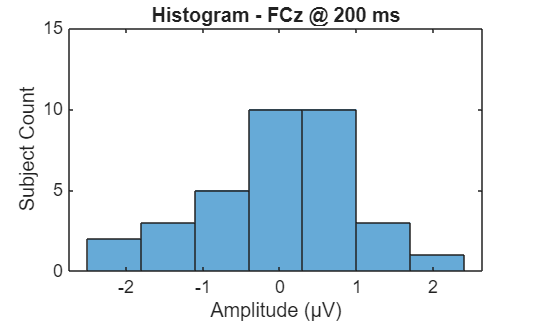

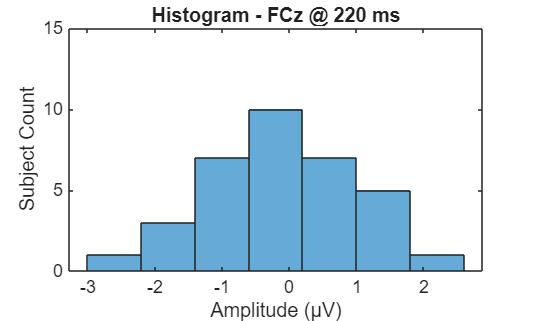

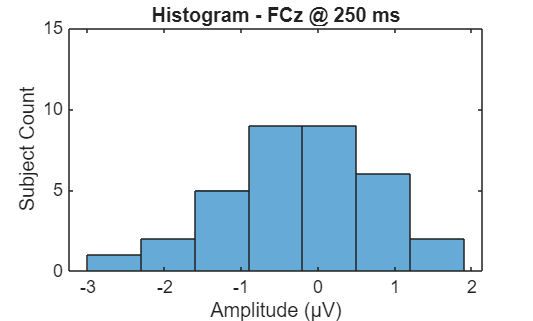

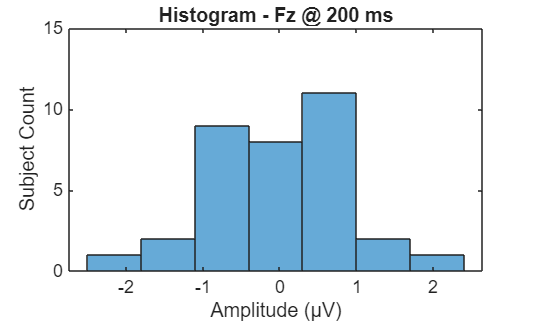

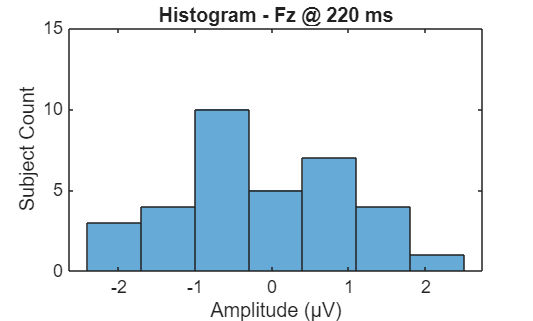

% timepoints approximately related to the N2 component

N2_TPs = [200, 220, 250];

amps_atN2TP = groupDat(:, N2_TPs(1));
n = height(amps_atN2TP); 
bin = ceil(log2(n) +1); % applies Sturge's formula to determine appropriate number of bins


for chan = 1:length(channels)
    % Get channel name
    chanName = channels(chan);
    
    % Extract data for that channel
    chanDat = allData(strcmp(allData.Channel, chanName), :);

    for TP = 1:length(N2_TPs)
        figure('WindowStyle','docked');

        Time = N2_TPs(TP);
        colName = "Time" + N2_TPs(TP);
        amps_atN2TP = chanDat.(colName);
        n = height(amps_atN2TP); 
        bin = ceil(log2(n) +1); % applies Sturge's formula to determine appropriate number of bins

        histogram(amps_atN2TP, bin);
        title(['Histogram - ', char(chanName), ' @ ', num2str(Time), ' ms']);
        xlabel('Amplitude (µV)');
        ylabel('Subject Count');
        ylim([0 15]);
    end
end

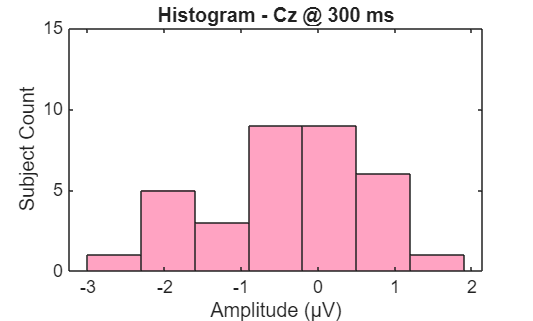

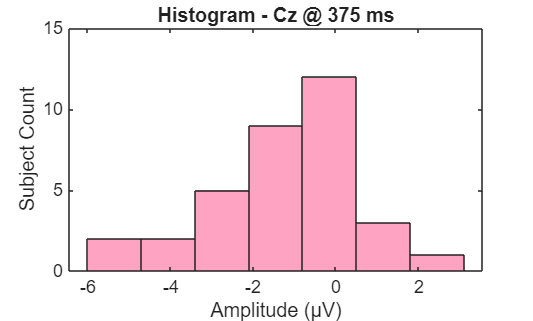

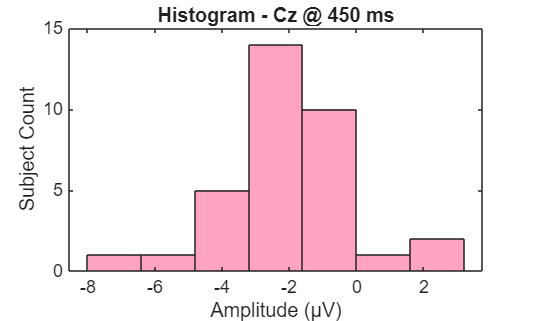

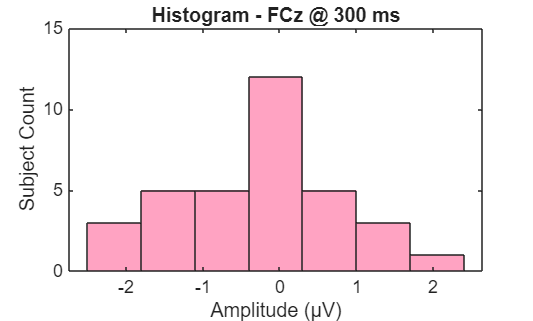

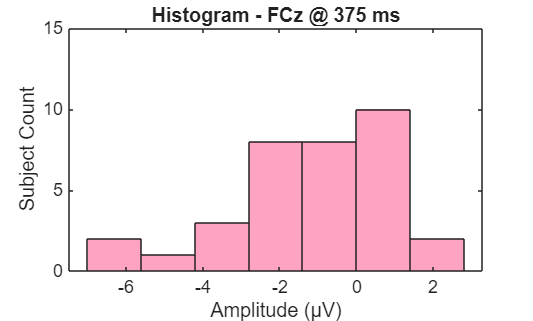

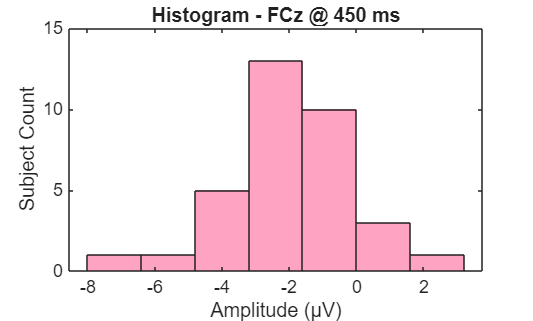

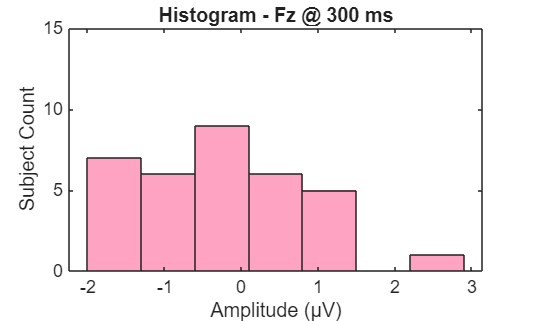

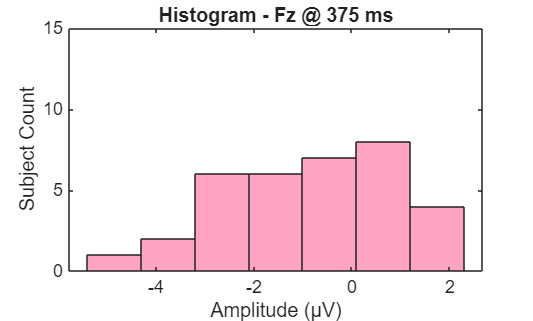


% timepoints approximately related to the N2 component

P3_TPs = [300, 375, 450];
for chan = 1:length(channels)
    % Get channel name
    chanName = channels(chan);
    
    % Extract data for that channel
    chanDat = allData(strcmp(allData.Channel, chanName), :);

    for TP = 1:length(P3_TPs)
        figure ('WindowStyle','docked');

        Time = P3_TPs(TP);
        colName = "Time" + P3_TPs(TP);
        amps_atN2TP = chanDat.(colName);
        n = height(amps_atN2TP); 
        bin = ceil(log2(n) +1); % applies Sturge's formula to determine appropriate number of bins

        histogram(amps_atN2TP, bin, ...
            'FaceColor', [1, 0.4, 0.6]);
        title(['Histogram - ', char(chanName), ' @ ', num2str(Time), ' ms']);
        xlabel('Amplitude (µV)');
        ylabel('Subject Count');
        ylim([0 15]);
    end
end

## Create Null Distribution %%

null_dist = [];
for perm = 1:nPermutations
    dataPerm = allData;
    dataPerm.Group = randi([1,2], height(dataPerm), 1);
    resultsStructPerm = perform_tTests(dataPerm, channels);

    % find null, permuted clusters
    clustersPerm = find_clusters(resultsStructPerm, null_alpha);

    if isempty(clustersPerm) % if no cluster, add 0 as the max_cluster_size for that permutation
        max_cluster_size = 0;
    else
        max_cluster_size = max([clustersPerm.Cluster_length]);
    end
    null_dist = [null_dist, max_cluster_size];
end

## Extract value for the 95th percentile of data in the null distribution %%

% min cluster is the minimum number of consecutive timepoints that must be
% significant for cluster to be significant

if max(null_dist) >= 1
    min_cluster_size = prctile(null_dist, 95);
else
    min_cluster_size = 1; % if all permutations yielded 0 for max cluster, set threshold to 1
end

# Cluster Based Permutation for ERP Analysis 

1) Permutation testing - randomly redistributes or "scrambles" data and reassigns to groups for nPermutations. Each permutation will result in a structured array of clusters. The largest cluster (i.e. the one with the most consecutively significant [at p <= 0.01] milliseconds) from each permutation will be added to the null distribution.

2) Parametric testing - T-test conducted at every millisecond of the ERP. After testing, clusters are computed. Clusters of size >= the 95th percentile of the null distribution will be considered significant at the 0.05 alpha level.

## T-tests 

% calculate t-statistics and p-values using t-test; returns a structured
% array
results = perform_tTests(allData, channels);

## Determine significant clusters

% use minimum cluster threshold calculated via the null permutation to evaluate whether or not a cluster in the
% true data should be considered statistically significant

clustersAll = find_clusters(results, alpha);
clustersSig = struct('Channel', {}, ...
    'Timepoint_start', {}, ...
    'Timepoint_end', {}, ...
    'Cluster_length', {});
clusterIDX = 1;
for cluster = 1:length(clustersAll)
    if clustersAll(cluster).Cluster_length >= min_cluster_size
        clustersSig(clusterIDX).Channel = clustersAll(cluster).Channel;
        clustersSig(clusterIDX).Timepoint_start = clustersAll(cluster).Timepoint_start;
        clustersSig(clusterIDX).Timepoint_end = clustersAll(cluster).Timepoint_end;
        clustersSig(clusterIDX).Cluster_length = clustersAll(cluster).Cluster_length;
        clusterIDX = clusterIDX + 1;
    end
end

# Final Data Visualization for CBPT script

creates a grand average ERP waveform and superimposes the standard error range over the grand average ERP wave shades regions where clusters are significant

## Grand Average ERP Waveforms with standard error

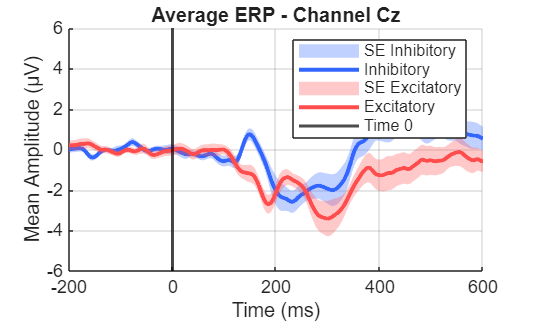

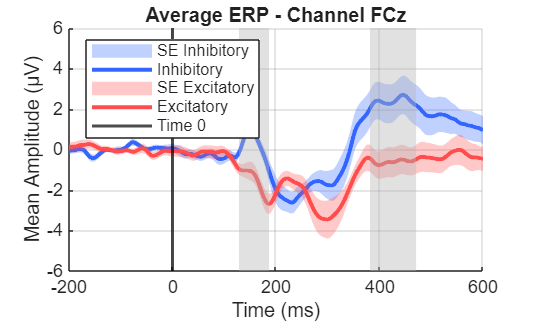

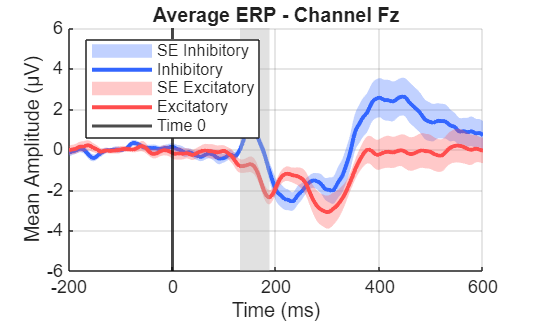

% define time windows for shading
clustersShade = struct();  % initialize empty struct

for i = 1:length(clustersSig)
    ch = clustersSig(i).Channel;
    startT = clustersSig(i).Timepoint_start;
    endT = clustersSig(i).Timepoint_end;

    if isfield(clustersShade, ch)
        clustersShade.(ch) = [clustersShade.(ch); startT endT];  % append
    else
        clustersShade.(ch) = [startT endT];  % first entry
    end
end

% Align with timepoint 0 (i.e. -200 to 600 timepoints instead of 0 to 800)
for i = 1:length(fields)
    ch = fields{i};
    % Convert sample indices to actual time values
    idx = clustersShade.(ch);  % e.g., [123 150]
    clustersShade.(ch) = time(idx);  % replaces with [time(123) time(150)]
end

% generate ERP wave forms with SE and cluster shading

time = linspace(-200, 600, timePoints);

groupColors = [
    0.2 0.4 1.0;   % Blue-ish for Group 1
    1.0 0.3 0.3    % Reddish for Group 2
];
for chan = 1:length(channels)
    % Get channel name
    chanName = channels(chan);
    
    % Extract data for that channel
    chanDat = allData(strcmp(allData.Channel, chanName), :);
    
    % Open figure ONCE per channel
    figure('WindowStyle','docked');
    hold on;

    for group = 1:length(groups)
        % Extract data for this group within the channel
        groupCode = group;  % 1 or 2
        groupDat = chanDat(chanDat.Group == groupCode, :);
        
        % Find amplitude columns
        ampCols = contains(groupDat.Properties.VariableNames, 'Time');
        
        % Compute mean across subjects
        meanAmplitudes = mean(groupDat{:, ampCols}, 1);  % 1 x 800
        se = std(groupDat{:, ampCols}, 0, 1) / sqrt(size(groupDat{:, ampCols}, 1)); 
        fill([time, fliplr(time)], ...
            [meanAmplitudes - se, ...
            fliplr(meanAmplitudes + se)], ...
            groupColors(group, :), ...
            'FaceAlpha', 0.3, ...
            'EdgeColor', 'none', ...
            'DisplayName', char("SE " + groups(group)));
        
        % Plot
        plot(time, meanAmplitudes, ...
            'DisplayName', groups(group), ...
            'Color', groupColors(group, :), ...
            'LineWidth', 2);
    end

    % Add shaded cluster regions if defined for this channel
    if isfield(clustersShade, char(chanName))
        thisCluster = clustersShade.(char(chanName));

        yMin = -6;
        yMax = 6;
    
        for i = 1:size(thisCluster, 1)
            x1 = thisCluster(i, 1);
            x2 = thisCluster(i, 2);
            fill([x1 x2 x2 x1], [yMin, yMin, yMax, yMax],...
                [0.7 0.7 0.7], 'FaceAlpha', 0.4, 'EdgeColor', 'none', ...
                'HandleVisibility', 'off');
        end
    end
    xlabel('Time (ms)');
    ylabel('Mean Amplitude (µV)');
    title(sprintf('Average ERP - Channel %s', chanName));
    ylim([-6 6]);
    xlim([min(time) max(time)]);
    xline(0, 'k', 'LineWidth', 1.5, 'DisplayName', 'Time 0');
    legend('Location', 'best');
    grid on;
end